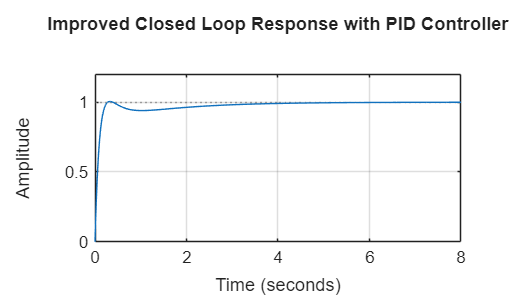

clc;
clear;
close all;

s = tf('s');

G = 1/(s^2 + 2*s + 5);

Kp = 40;
Ki = 25;
Kd = 12;

C = pid(Kp, Ki, Kd);

T = feedback(C*G, 1);

figure;
step(T);
grid on;
title('Improved Closed Loop Response with PID Controller');


info_closed = stepinfo(T)

info_closed = struct with fields:
         RiseTime: 0.1530
    TransientTime: 2.8965
     SettlingTime: 2.8965
      SettlingMin: 0.9034
      SettlingMax: 1.0047
        Overshoot: 0.4684
       Undershoot: 0
             Peak: 1.0047
         PeakTime: 0.3272
